#  Kulite Calibrations

% Load in raw voltage output data before executing 

% Convert Data tables into arrays
 
% KCal1 = table2array(KCal1);
% KCal2 = table2array(KCal2);
% KCal3 = table2array(KCal3);
% KCal4 = table2array(KCal4);
% KCal5 = table2array(KCal5);
% KCal6 = table2array(KCal6);
% KCal7 = table2array(KCal7);
% 
% DCal1 = table2array(DCal1);
% DCal2 = table2array(DCal2);
% DCal3 = table2array(DCal3);
% DCal4 = table2array(DCal4);
% DCal5 = table2array(DCal5);
% 
% Run1_DT = table2array(Run1_DT);
% Run2_DT = table2array(Run2_DT);
% Run3_DT = table2array(Run3_DT);
% Run4_DT = table2array(Run4_DT);
% Run5_DT = table2array(Run5_DT);
% Run6_DT = table2array(Run6_DT);
% Run7_DT = table2array(Run7_DT);
% Run8_DT = table2array(Run8_DT);
% Run9_DT = table2array(Run9_DT);
% Run10_DT = table2array(Run10_DT);
% Run11_DT = table2array(Run11_DT);
% Run12_DT = table2array(Run12_DT);
% Run13_DT = table2array(Run13_DT);
% Run14_DT = table2array(Run14_DT);
% Run15_DT = table2array(Run15_DT);
% Run16_DT = table2array(Run16_DT);
% Run17_DT = table2array(Run17_DT);
%
% Run1_K = table2array(Run1_K);
% Run2_K = table2array(Run2_K);
% Run3_K = table2array(Run3_K);
% Run4_K = table2array(Run4_K);
% Run5_K = table2array(Run5_K);
% Run6_K = table2array(Run6_K);
% Run7_K = table2array(Run7_K);
% Run8_K = table2array(Run8_K);
% Run9_K = table2array(Run9_K);
% Run10_K = table2array(Run10_K);
% Run11_K = table2array(Run11_K);
% Run12_K = table2array(Run12_K);
% Run13_K = table2array(Run13_K);
% Run14_K = table2array(Run8_K);
% Run15_K = table2array(Run9_K);
% Run16_K = table2array(Run10_K);
% Run17_K = table2array(Run11_K);




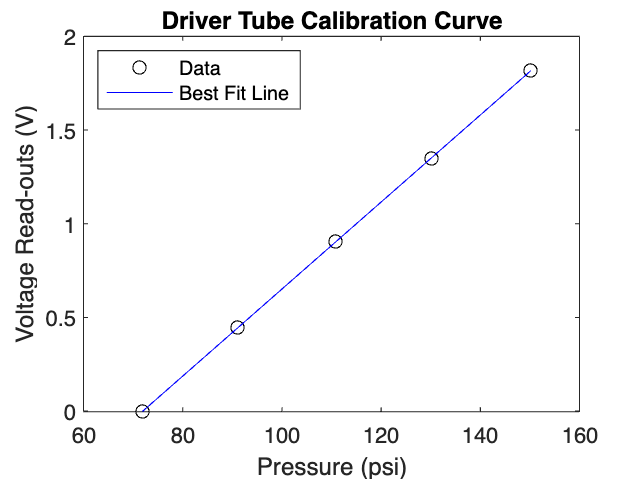

% Plot Driver tube and Kulite calibration curves

% DCal data
DCal_points = [sum(DCal1)./(height(DCal1)), sum(DCal2)./(height(DCal2)), sum(DCal3)./(height(DCal3)), sum(DCal4)./(height(DCal4)), sum(DCal5)./(height(DCal5))];
DCal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
DCal_fit_coeffs = polyfit(DCal_pressures, DCal_points, 1);
DCal_fit = polyval(DCal_fit_coeffs, DCal_pressures);

% Plot DCal data and best-fit line
figure;
plot(DCal_pressures, DCal_points, 'ko', 'DisplayName', 'Data');
hold on
plot(DCal_pressures, DCal_fit, 'b-', 'DisplayName', 'Best Fit Line');
hold off
legend('Location', 'northwest')
xlabel('Pressure (psi)');
ylabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');

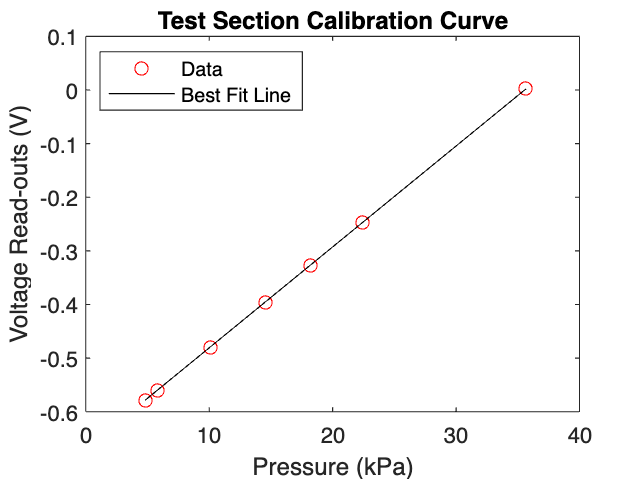


% For KCal data
KCal_points = [sum(KCal1)./(height(KCal1)), sum(KCal2)./(height(KCal2)), sum(KCal3)./(height(KCal3)), sum(KCal4)./(height(KCal4)), sum(KCal5)./(height(KCal5)), sum(KCal6)./(height(KCal6)), sum(KCal7)./(height(KCal7))];
KCal_pressures = [35.65 22.38 18.18 14.55 10.09 5.80 4.80];

% Find best-fit line for KCal data
KCal_fit_coeffs = polyfit(KCal_pressures, KCal_points, 1);
KCal_fit = polyval(KCal_fit_coeffs, KCal_pressures);

% Plot KCal data and best-fit line
figure;
plot(KCal_pressures, KCal_points, 'ro', 'DisplayName', 'Data');
hold on
plot(KCal_pressures, KCal_fit, 'k-', 'DisplayName', 'Best Fit Line');
hold off
legend('Location', 'northwest')
xlabel('Pressure (kPa)');
ylabel('Voltage Read-outs (V)');
title('Test Section Calibration Curve');

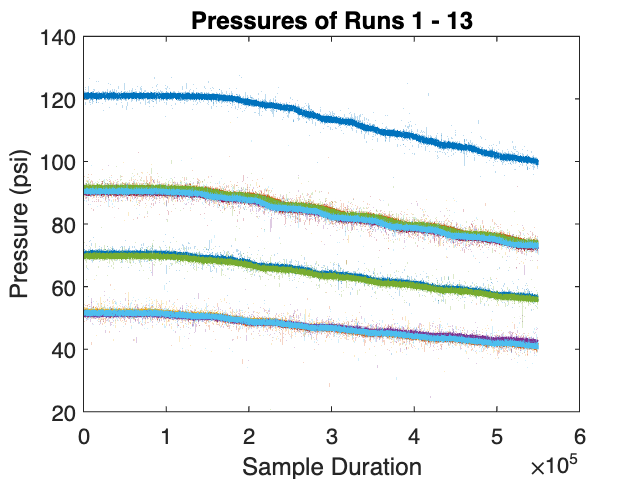

% Plots of Test Run Driver Tube Pressures
% Use best fit coefficients from DT calibration to calculate pressures

Press_DTRun1 = (Run1_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun2 = (Run2_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun3 = (Run3_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun4 = (Run4_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun5 = (Run5_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun6 = (Run6_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun7 = (Run7_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun8 = (Run8_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun9 = (Run9_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun10 = (Run10_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun11 = (Run11_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun12 = (Run12_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DTRun13 = (Run13_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
% Press_DTRun14 = (Run14_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
% Press_DTRun15 = (Run15_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
% Press_DTRun16 = (Run16_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
% Press_DTRun17 = (Run17_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
% Press_DTRun18 = (Run18_DT - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);

% Plot Pressures vs Sample Duration

plot(Press_DTRun1, 'DisplayName', 'Test 1');
hold on;
plot(Press_DTRun2, 'DisplayName', 'Test 2');
plot(Press_DTRun3, 'DisplayName', 'Test 3');
plot(Press_DTRun4, 'DisplayName', 'Test 4');
plot(Press_DTRun5, 'DisplayName', 'Test 5');
plot(Press_DTRun6, 'DisplayName', 'Test 6');
plot(Press_DTRun7, 'DisplayName', 'Test 7');
plot(Press_DTRun8, 'DisplayName', 'Test 8');
plot(Press_DTRun9, 'DisplayName', 'Test 9');
plot(Press_DTRun10, 'DisplayName', 'Test 10');
plot(Press_DTRun11, 'DisplayName', 'Test 11');
plot(Press_DTRun12, 'DisplayName', 'Test 12');
plot(Press_DTRun13, 'DisplayName', 'Test 13');
% plot(Press_DTRun14, 'DisplayName', 'Test 14');
% plot(Press_DTRun15, 'DisplayName', 'Test 15');
% plot(Press_DTRun16, 'DisplayName', 'Test 16');
% plot(Press_DTRun17, 'DisplayName', 'Test 17');
% plot(Press_DTRun18, 'DisplayName', 'Test 18');


% Adding labels and legend
title('Pressures of Runs 1 - 13');
xlabel('Sample Duration');
ylabel('Pressure (psi)');
% legend('show');

hold off;

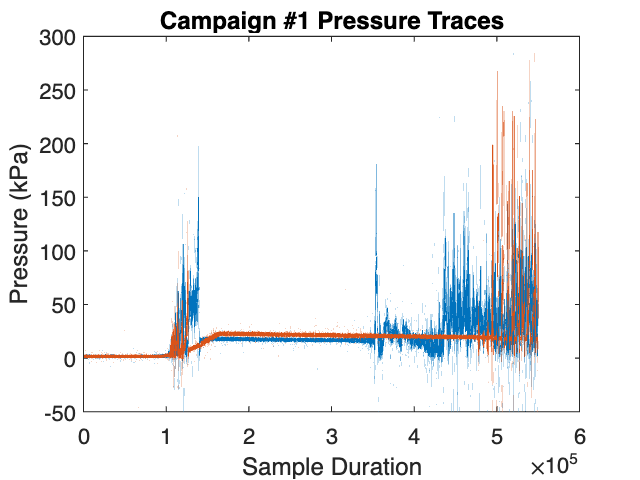

% Plots of Test Run Kulite Pressures
% Use best fit coefficients from Kulite calibration to calculate pressures

Press_KRun1 = (Run1_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun2 = (Run2_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun3 = (Run3_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun4 = (Run4_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun5 = (Run5_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun6 = (Run6_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun7 = (Run7_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun8 = (Run8_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun9 = (Run9_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun10 = (Run10_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun11 = (Run11_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun12 = (Run12_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun13 = (Run13_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun14 = (Run14_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun15 = (Run15_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun16 = (Run16_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun17 = (Run17_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);
Press_KRun18 = (Run18_K - KCal_fit_coeffs(2)) / KCal_fit_coeffs(1);

figure;

plot(Press_KRun1, 'DisplayName', 'Test 1');
hold on
% plot(Press_KRun2, 'DisplayName', 'Test 2');
% plot(Press_KRun3, 'DisplayName', 'Test 3');
% plot(Press_KRun4, 'DisplayName', 'Test 4');
% plot(Press_KRun5, 'DisplayName', 'Test 5');
% plot(Press_KRun6, 'DisplayName', 'Test 6');
% plot(Press_KRun7, 'DisplayName', 'Test 7');
% plot(Press_KRun8, 'DisplayName', 'Test 8');
% plot(Press_KRun9, 'DisplayName', 'Test 9');
% plot(Press_KRun10, 'DisplayName', 'Test 10');
plot(Press_KRun11, 'DisplayName', 'Test 11');
% plot(Press_KRun12, 'DisplayName', 'Test 12');
% plot(Press_KRun13, 'DisplayName', 'Test 13');
% plot(Press_KRun14, 'DisplayName', 'Test 14');
% plot(Press_KRun15, 'DisplayName', 'Test 15');
% plot(Press_KRun16, 'DisplayName', 'Test 16');
% plot(Press_KRun17, 'DisplayName', 'Test 17');
% plot(Press_KRun18, 'DisplayName', 'Test 18');

% Adding labels and legend
title('Campaign #1 Pressure Traces');
xlabel('Sample Duration');
ylabel('Pressure (kPa)');
% legend('Location', 'northwest','Fontsize', 18);

hold off;